# **Численные методы в СПб АУ РАН - Часть 2**

## **Задание по практике №7**

Кузьмичев Артём, 4 курс

## **№6 (алгоритмы и программы к разделу 9.9)**

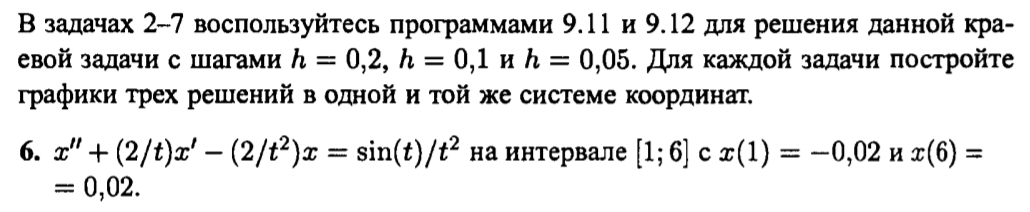

#### Постановка краевой задачи

Граничные условия:

a = 1;
b = 6;
alpha = -0.02;
beta = 0.02;

Сравнивая вид уравнения, получим функции-коэффициенты p,q,r


$${x^{\prime } }^{\prime } \left(t\right)=p\left(t\right)x^{\prime } \left(t\right)+q\left(t\right)x\left(t\right)+r\left(t\right)$$



$${x^{\prime } }^{\prime } \left(t\right)+\frac{2}{t}x^{\prime } \left(t\right)-\frac{2}{t^2 }x\left(t\right)=\frac{\sin \left(t\right)}{t^2 }$$


syms p(t) q(t) r(t)
p(t) = -2/t;
q(t) = 2/t^2;
r(t) = sin(t)/t^2;

### Точное решение

Используем встроенную функцию *dsolve* для точного решения:

syms x(t)
eqn = diff(x,t,2) == p*diff(x,t)+q*x+r;
cond = [x(a) == alpha,x(b) == beta] ;
xSol(t) = dsolve(eqn, cond)

$$xSol(t) = \frac{\frac{t^{3}\,\left(\frac{\mathrm{cosint}\left(1\right)}{215}-\frac{216\,\mathrm{cosint}\left(6\right)}{215}+\frac{\cos\left(1\right)}{215}-\frac{6\,\cos\left(6\right)}{215}-\frac{2\,\sin\left(1\right)}{215}+\frac{37\,\sin\left(6\right)}{215}+\frac{111}{10750}\right)}{3}-\frac{\sin\left(t\right)}{3}-\frac{t^{2}\,\sin\left(t\right)}{3}+\frac{t\,\cos\left(t\right)}{3}+\frac{t^{3}\,\mathrm{cosint}\left(t\right)}{3}}{t^{2}}-\frac{\frac{72\,\mathrm{cosint}\left(1\right)}{215}-\frac{72\,\mathrm{cosint}\left(6\right)}{215}+\frac{72\,\cos\left(1\right)}{215}-\frac{2\,\cos\left(6\right)}{215}-\frac{144\,\sin\left(1\right)}{215}+\frac{37\,\sin\left(6\right)}{645}+\frac{126}{5375}}{t^{2}}$$

#### Решение краевой задачи методом конечных разностей

Зададим различные величины шага:

h1  = 0.2;
h2  = 0.1;
h3  = 0.05;

Подставим исходные данные в функцию *findiff*

S1 = findiff(p,q,r,a,b,alpha,beta,h1);
S2 = findiff(p,q,r,a,b,alpha,beta,h2);
S3 =findiff(p,q,r,a,b,alpha,beta,h3);

Построим получившиеся решения на одном графике:

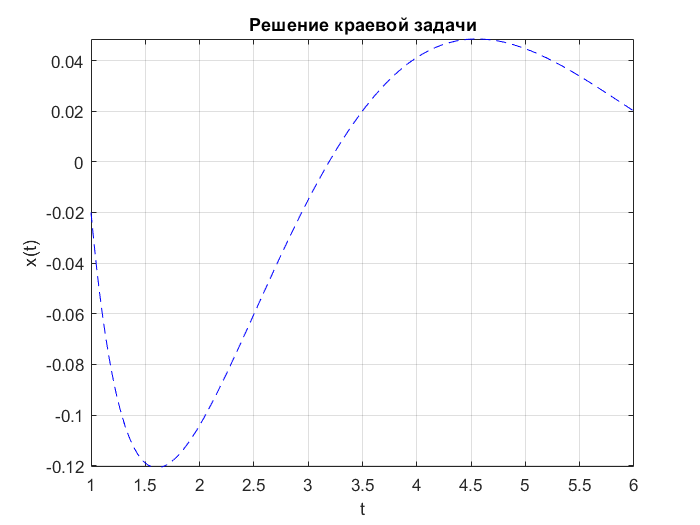

figure
fplot(xSol,[a b],'--b','LineWidth',0.1)
title('Решение краевой задачи');
xlabel('t');
ylabel('x(t)');
grid on
hold on


plot(S1(:,1),S1(:,2),"r",'LineWidth',0.1)
plot(S2(:,1),S2(:,2),"g",'LineWidth',0.1)
plot(S3(:,1),S3(:,2),"k",'LineWidth',0.1)
legend('h = 0.2','h = 0.1','h = 0.05','Аналитическое решение',"Location","best")

## Приложение

#### Определение функции, осуществляющей решение трёхдиагональной системы

function X = trisys(A, D, C, B)
%Вход   -   A       - поддиагональ матрицы коэффициентов
%       -   D       - главная диагональ матрицы коэффициентов
%       -   C       - наддиагональ матрицы коэффициентов
%       -   B       - вектор постоянных линейной системы
%Выход  -   X       - вектор решений

N = length(B);
for k = 2:N
    mult = A(k-1)/D(k-1);
    D(k)= D(k) - mult*C(k-1);
    B(k)= B(k) - mult*B(k-1);
end
X(N)=B(N)/D(N);
for k = N-1:-1:1
    X(k)=(B(k)-C(k)*X(k+1))/D(k);
end
end

#### Определение функции, осуществляющей приближённое решение краевой задачи

function F =findiff(p,q,r,a,b,alpha,beta,h)
%Вход - p,q и r - коэффициенты функций из x''(t) = p(t)x'(t)+q(t)x(t)+r(t)
%	- а и b - левая и правая крайние точки
%	- alpha=x(a) и beta=x(b)
%	- g - шаг
%Выход - F=[T' X'], где Т' - вектор абсцисс размера 1xN
%                   и   X' - вектор ординат размера 1xN

%Инициализация векторов и числа шагов Т
N=floor((b-a)/h);

T=zeros(1,N+1);
X=zeros(1,N-1);
Va=zeros(1,N-2);
Vb=zeros(1,N-1);
Vc=zeros(1,N-2);
Vd=zeros(1,N-1); 


%Вычисление вектора постоянных В в АХ=В 
Vt=double(a+h:h:a+h*(N-1));
Vb=double(-h^2*r(Vt));
Vb(1)=double(Vb(1)+(1+h/2*p(Vt(1)))*alpha);
Vb(N-1)=double(Vb(N-1)+(1-h/2*p(Vt(N-1)))*beta);

%Вычисление главной диагонали А в AX=B 
Vd=double(2+h^2*q(Vt));

%Вычисление наддиагонали А в AX=B 
Vta=double(Vt(1,2:N-1));
Va=double(-1-h/2*p(Vta));

%вычисление поддиагонали А в AX=B 
Vtc=double(Vt(1,1:N-2));
Vc=double(-1+h/2*p(Vtc));

%Решение AX=B с использованием trisys 
X=trisys(Va,Vd,Vc,Vb);
T=[a,Vt,b];
X=[alpha,X,beta];
F=[T' X'];
end